# Geometrically nonlinear von Karman beam under Stochastic Excitation

Finite element model from the following reference:

 Jain, S., Tiso, P., & Haller, G. (2018). Exact nonlinear model reduction for a von Kármán beam: slow-fast decomposition and spectral submanifolds. *Journal of Sound and Vibration*, *423*, 195–211. [https://doi.org/10.1016/J.JSV.2018.01.049](https://doi.org/10.1016/J.JSV.2018.01.049)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

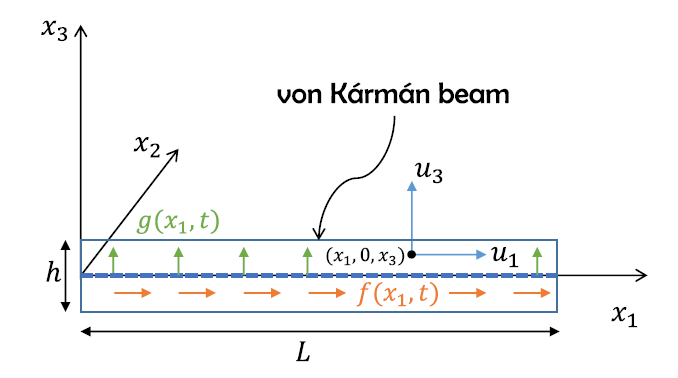

**system parameters**

nElements = 10;
epsilon = 1e-3;

## generate model

Building FE model


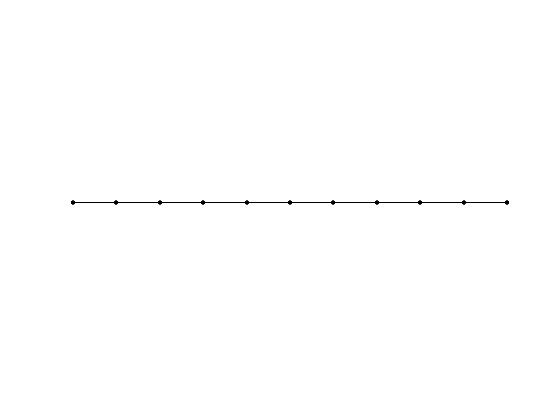

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


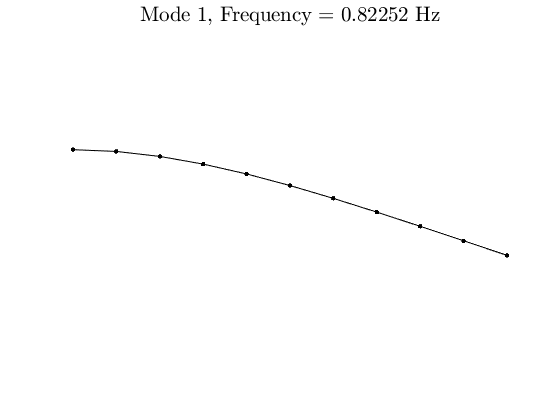

Assembling external force vector
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:00


[M,C,K,fnl,outdof,eMass] = build_model(nElements);

n = length(M);

Number of degrees of freedom = 30


Phase space dimensionality = 60


nRealization=20;
T0=100; %% PSD frequency domain resolution is ~ 1/T0
nPoints=2^14; %% control the accuracy of numerical differential equation

[filterPSD, stochastic_f] = build_stochasticF(eMass,n,epsilon);
disp(['Number of degrees of freedom = ' num2str(n)])

## Dynamical system setup 

We consider the stochastic forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}_{nl}(\mathbf{x},\dot{\mathbf{x}})=\mathbf{f}_{stochastic}(\mathbf{x},t)$$


We assume stochastic forcing of the form that has a specific PSD. We identify the stochastic forcing by input a white noise to a second order system:

                                            
$$\mathbf{M_i}\ddot{\mathbf{x}}+\mathbf{C_i}\dot{\mathbf{x}}+\mathbf{K_i}\mathbf{x}=\mathbf{W}_{white noise}$$


We take the PSD of the response of transverse direction of the last element $<\mathbf x_3,\mathbf x_3>$ over the time domain as the input to the system.

Setting for the SDE solver and allocate desired output PSD pairs

SS = StochasticSystem();

set(SS,'filterPSD',filterPSD,'linear',false)
set(SS,'M',M,'C',C,'K',K,'fnl',fnl,'gFactor',-eMass);
set(SS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.691472e-04
modal damping ratio for 2 mode is 2.313481e-03
modal damping ratio for 3 mode is 6.479248e-03
modal damping ratio for 4 mode is 1.270560e-02
modal damping ratio for 5 mode is 2.103617e-02

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0000 + 0.0517i
  -0.0000 - 0.0517i
  -0.0007 + 0.3239i
  -0.0007 - 0.3239i
  -0.0059 + 0.9071i
  -0.0059 - 0.9071i
  -0.0226 + 1.7786i
  -0.0226 - 1.7786i
  -0.0620 + 2.9444i
  -0.0620 - 2.9444i



set(SS.SSOptions,'ssMethod','indirect')
SS.add_random_forcing(nRealization, T0, nPoints,outdof);

%%%%%%%% Above is forcing setting and set to DynamicalSystem class
clusterRun=true; %% if the script is run on local or cluster.
method="filter ImplicitMidPoint";
PSDpair=[n-1,n-1];

## Linear Modal analysis ,Full System Calculation and SSM setup

[V, D, W] = SS.linear_spectral_analysis();
firts_res=abs(imag(D(1)));

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3247
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 + 5.1681i
  -0.0019 - 5.1681i
  -0.0019 - 5.1681i
  -0.0019 - 5.1681i
  -0.0019 - 5.1681i

sigma_in = 3247


SS.sdeImpTimeDisp = false;
[w,outputPSD] = SS.monte_carlo_average(method,PSDpair,nRealization,clusterRun);

**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);


## Power Spectral Density using SSMs

Obtaining PSD from approximation order

order = 5;
freq_range=[0 10];
S.ssmSEulerTimeDisp = false;
[wss,ssmPSD]=S.extract_PSD(PSDpair, order,'filt',freq_range,clusterRun);